# Exercise 1

## Probabilistic Mapping With the Bump Sensor

### About This Exercise

In early exercises you charted unknown maps, first by bumping into walls and recording the location where the bump occurred, and second by transforming the range data from the LIDAR sensor into the global frame. Now you will start building the map probabilistically using uncertain sensor readings. Here, you will develop probabilistic maps where the pose is known. Later in the course you will implement the probabilistic localization techniques you've used previously simultaneously with probabilistic mapping, in what is called **Simultaneous Localization and Mapping**, or **SLAM.**

In this first exercise, you will revisit the Roomba-like method of tactile navigation by bumping into walls and changing direction. Before, you simply plotted the location of the robot when a bump occurred to indicate the presence of an occupied part of the map where a wall was located. However, it is better to represent the map probabilistically, as there may be uncertainties in the sensor such as false triggers or missed triggers.  You can represent that uncertainty by using an occupancy grid to divide the space into cells that are either occupied with a wall or free. You will then calculate the probability any particular cell is occupied given the presence or absence of a bump at every point along the robot's trajectory. 

**By the end of this exercise, you'll be able to: **

- **Use probabilistic mapping to update an occupancy grid that builds a map based on bump sensor data **

### Log Odds

We need to determine whether each cell in the grid is either free or occupied to build the map using the robot's sensors. Given the binary choice for each cell, we can use what is called a binary Bayes filter.  We update the probability the cell is free by combining the prior knowledge with the new sensor reading. However, it is mathematically simpler to update the log of the odds that the cell is occupied versus unoccupied. Odds can therefore range from 0 (where there is no chance the cell is occupied) to infinity (where there is no chance the cell is unoccupied), and odd of 1 is equal chance of being occupied and unoccupied 


$$Odds(m) = \frac{p(m=1)}{p(m=0)} = \frac{p(m=1)}{1-p(m=1)}$$



$$log(Odds) = log(p(m=1)) - log(p(m=0)) = -log(1 / p(m=1) -1)$$


plot_title = "Exercise 1a"

plot_title = "Exercise 1a"

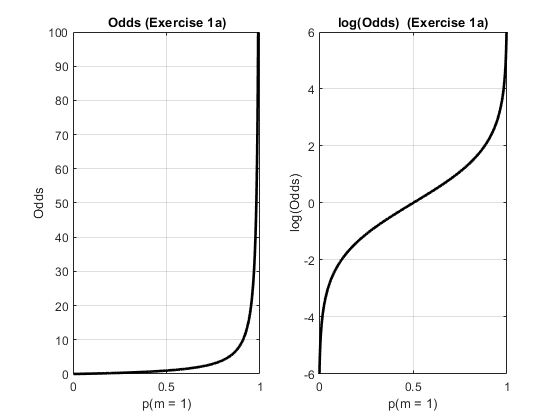

plotOdds(plot_title); 

We instead take the log of the odds as shown above for two reasons, demonstrated by the plot. The first is that it transforms the unbalanced range of 0 to infinity to a symmetrical range from -infinity to infinity, where 0 is now equal chance of being occupied and free. It is symmetrical as a negative value gives the same chance of being unoccuped as that same positive value does for being occupied 

Secondly, when propagating the **odds** from one time point to the next, we must multiply the initial (or prior) odds with the odds from the last step and the odds from the new observation. When we propagate the **log odds**, the multiplication operation turns into a sum. We will apply this operation to each grid cell in the map as we gain new information about whether a bump has or has not occurred.

**Creating the Occupancy Map**

To create the occupancy map, we need to divide the space into grid cells to represent the space. We are now assuming we have perfect localization (we will bring back in probabilistic localization in the second half of this course).

- First we need to decide how finely to divide the grid. For now we'll assume a square grid and *gridcells* is the numer of cells in in both the x and y direction. 

gridcells = 30; %Change value here

- Given the number of grid cells in each direction and measured length of each side  (*mapsize*) of the represented area , we can determine the resolution of the the occupancy map.  We can use meshgrid to create the X and Y matrices that contain the values for all of the grid edges of the occupancy map. In this case, the center of the grid is (0,0). 

mapsize = 4;
x = linspace(-mapsize/2,mapsize/2,gridcells+1);
y = x;
[X,Y] = meshgrid(x,y);

- Next, we'll generate some random probabilities of being occupied to fill our grid and calculate the log odds and put them into a matrix Z that has elements which correspond to the grid **cells**.

pocc = rand(gridcells);

- Calculate the log odds using the formula above.

**Complete the code below.**

Z = -log(1./pocc - 1); 

- Finally, we'll plot the log odds to the grid using the imagesc function. It takes in the midpoint X and Y coordinates of the grid cells, the cell value, and the color limits. We use the grayscale colormap, where black is higher odds of being occupied and white is higher odds of being unoccupied. In the end, we would like to categorize each cell as either unoccupied or occupied, or unknown. Therefore we neet to set a lower and upper cutoff, which can be depicted by the limits to the colormap in the grid plot. What would a good cut-off be given the relationship between probability and log odds graphed above?

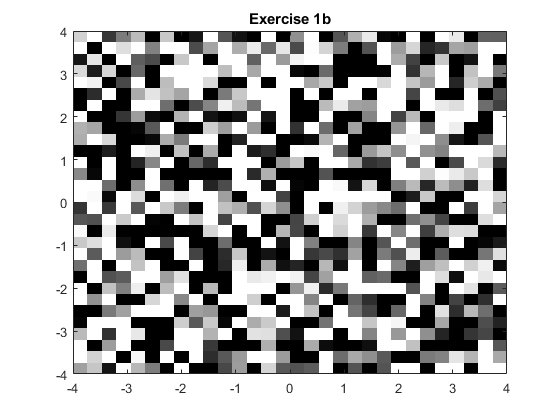

lim = 1; %Change value here
figure;
imagesc((X(1,1:end-1)+X(1,2:end))./2,(Y(1:end-1,1)+Y(2:end,1))./2,Z,[-lim,lim]);
set(gca,'YDir','normal')
colormap(flipud(gray));
plot_title = "Exercise 1b"; 
title(plot_title); 

### logOddsBump

Now that we have a grid, you will create a function that will update the log odds for each grid cell according an **Inverse Measurement Model** of the bump sensor. An inverse measurement model gives the expected map given a particular measurment and current pose (rather than what the measurement is given the map and the pose).

[► Complete the inverse measurement model in the logOddsBump function](matlab:open('./logOddsBump.mlx'))

Once it is finished, let's test one step:

- First, zLast and zPrior should be initialized to 0, indicating a 50% chance each cell is occupied. We add a little bit of noise just so that we can still see the grid.

Zlast = .05*randn(gridcells);
Zprior = zeros(gridcells);

- Next, we set a pose and measurement (in this case, we'll assume a bump occured on the middle sensor). **Note: **Position is represented using a 3-by-1 vector. 

pose = [1; 1; pi/2];
bump = [0; 0; 0];

- Now let's update Z using the logOddsBump function

Z = logOddsBump(X,Y,Zlast,Zprior,pose,bump);
plot_title = "Exercise 1c"; 
plotOddsUpdate(X,Y,Zlast,Z,lim,pose, plot_title);

- You can run this section again after changing bump to be all zeros to make sure the map gets updated appropriately.

### backupBumpMapping

Finally, lets use our mapping function to create a better version of the backupBump function from MAE101M3E1. Instead of simply plotting the robot whenever we encounter a bump, you will plot the grid map with the current log odds of each cell being occupied given the trajectory of the robot and the bump sensor measurement.

[► Complete the backupBumpMapping function](matlab:open('./backupBumpMapping.mlx'))

Once you complete the function:

1) Run the simulator,

2) Load up the map called Map104S.txt

3) Set the starting position somewhere within the map, and start the automatic control function. 

4) Change the gridsize and the color limits to see the effect on the map.

There are ways to improve the mapping using the bump sensor. For example, the actual Create robot (which we are simulating) has three bump sensors along the front semicircle of the robot. How might you change the inverse sensing model to utilize all three sensors? For an extra challenge, implement such a model into the logOddsBump function.

### Finished!

You have now implemented probabalistic mapping with the bump sensor. As you've seen, this gives more information than just plotting the location of bumps, as it shows known open spaces, known occupied spaces, and unknown spaces you might want to direct the robot to explore. In the next exercise you will create a similar function to logOddsBump using the LIDAR range sensor.